# Replicating EMG Fatigue Results

## Clear Workspace (Optional)

clear all
clc

## Load Data

Data was recorded using the Ripple system, and it was saved as a `.ns2` file. I am using a script written by Tyler to import the image into a MATLAB-readable format.

[head, data] = read_nsx_file('File', '..\..\..\data\CJT_RandLarm_LthenRFatigue_32x3_c1blank_c2Rarm_c3Larm_Rdominate_30secRest_4minFatigue_3minrest.ns3');

Loading 0.3 GB of data


## Validate Data

ch_idx = 75;
ch_signal = data(ch_idx, :);

signalAnalyzer(ch_signal, 'SampleRate', head.Fs)

## Decimate Data

For my purposes, a sampling rate of 2 kHz is unnecessary, and makes visualizing data much harder due to the number of points in the dataset. Therefore I apply a decimation filter, which in theory applies a low-pass(anti-aliasing filter) followd by a downsampling operation. I have set the new frequency to 1 kHz because I am only interested in the 0-500 Hz frequency band.

dec_factor = 2;
fs_dec = head.Fs/dec_factor;

ch_signal_dec = decimate(double(ch_signal), dec_factor);
ch_signal_dec_tb = timetable(ch_signal_dec', 'SampleRate', fs_dec)

ch_signal_dec_tb = 691986×1 timetable
      Time        Var1  
    _________    _______

    0 sec        -41.272
    0.001 sec    -38.608
    0.002 sec     96.356
    0.003 sec    -47.212
    0.004 sec    -46.211
    0.005 sec     80.634
    0.006 sec    -72.378
    0.007 sec    -50.797
    0.008 sec     108.72
    0.009 sec     40.471
    0.01 sec      -58.53
    0.011 sec    -32.375
    0.012 sec     37.705
    0.013 sec     15.365
    0.014 sec    -8.5232
    0.015 sec    -14.027


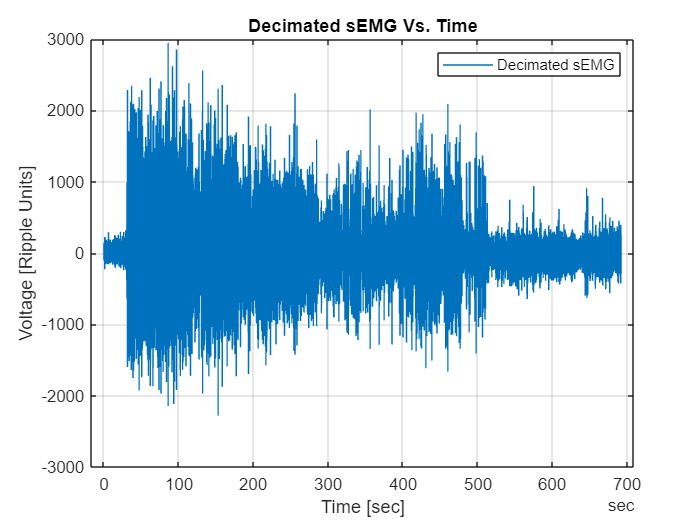

plot(ch_signal_dec_tb.Time, ch_signal_dec_tb.Var1)
grid on
legend("Decimated sEMG")
title("Decimated sEMG Vs. Time")
xlabel("Time [sec]")
ylabel("Voltage [Ripple Units]")

## Apply bandpass filter to decimated signal

filt_order = 4;
f_nyq = fs_dec /2;
fc1 = 10;
fc2 = 450;
[b, a] = butter(filt_order, [fc1, fc2]/f_nyq, 'bandpass');
ch_signal_filt = filtfilt(b, a, ch_signal_dec);
ch_signal_filt_tb = timetable(ch_signal_filt', 'SampleRate', fs_dec)

ch_signal_filt_tb = 691986×1 timetable
      Time        Var1  
    _________    _______

    0 sec        -3.3722
    0.001 sec    -1.8994
    0.002 sec     132.15
    0.003 sec    -12.124
    0.004 sec    -12.625
    0.005 sec     113.97
    0.006 sec    -41.041
    0.007 sec    -19.367
    0.008 sec     137.83
    0.009 sec     69.811
    0.01 sec     -31.543
    0.011 sec    -5.3545
    0.012 sec     62.726
    0.013 sec     39.891
    0.014 sec     14.608
    0.015 sec     7.9955


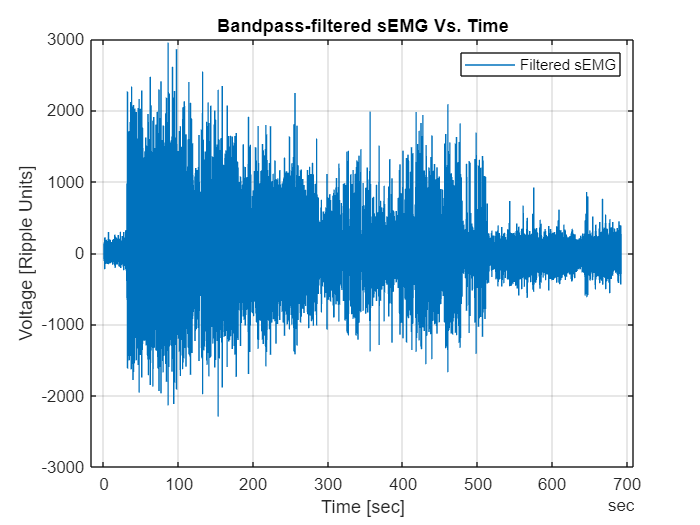

plot(ch_signal_filt_tb.Time, ch_signal_filt_tb.Var1)

grid on
legend("Filtered sEMG")
title("Bandpass-filtered sEMG Vs. Time")
xlabel("Time [sec]")
ylabel("Voltage [Ripple Units]")

## Visualize Spectral Qualities of the Data

signalAnalyzer(ch_signal_filt, 'SampleRate', fs_dec)

## Compute Median Frequency (MDF)

It's hard to find window sizes in the literature, but in the paper by Sun et al. They use a 0.1 sec window to validate MDF between MATLAB and a neuromorphic chip

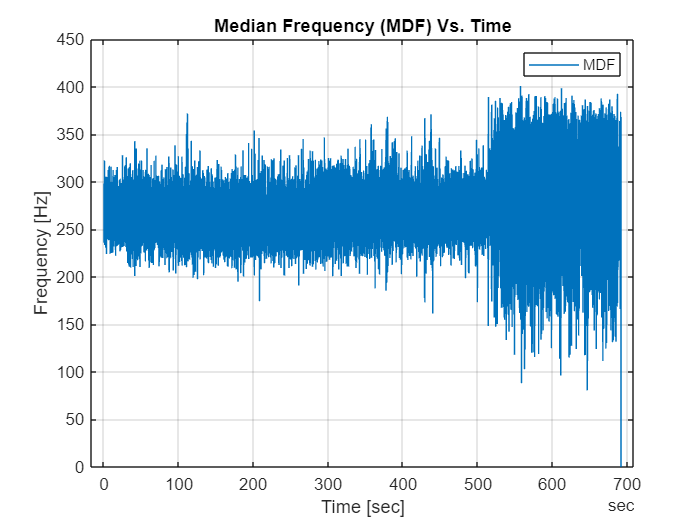

moving_MDF = @(x)medfreq(x, fs_dec);

window_length = 0.1*fs_dec;

output = zeros(length(ch_signal_filt), 1);

for i = 1:length(ch_signal_filt) - window_length
    window_signal = ch_signal_filt(1, i:i+window_length);
    output(i) = moving_MDF(window_signal);
end

ch_signal_mdf_tb = timetable(output, 'SampleRate', fs_dec);

plot(ch_signal_mdf_tb.Time, ch_signal_mdf_tb.output)
grid on
legend("MDF")
title("Median Frequency (MDF) Vs. Time")
xlabel("Time [sec]")
ylabel("Frequency [Hz]")

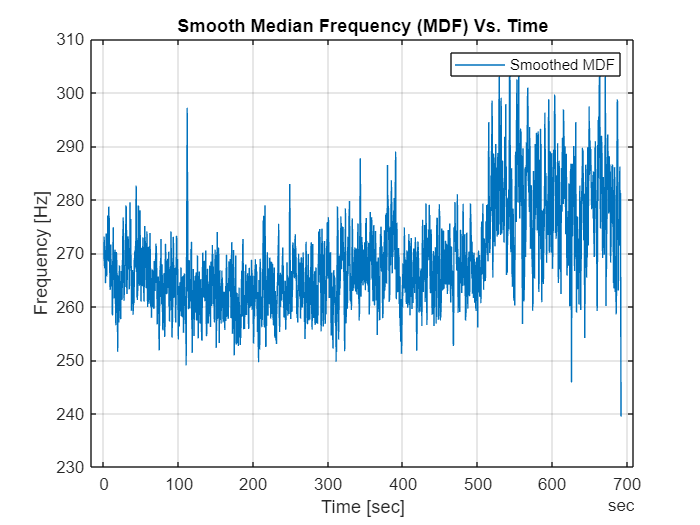

ch_signal_smooth_mdf_tb = timetable(movmean(output, 1*fs_dec), 'SampleRate', fs_dec);
plot(ch_signal_smooth_mdf_tb.Time, ch_signal_smooth_mdf_tb.Var1)

grid on
legend("Smoothed MDF")
title("Smooth Median Frequency (MDF) Vs. Time")
xlabel("Time [sec]")
ylabel("Frequency [Hz]")